# Model Validation Via Result Replication

To validate our implementation of the equilibrium model from Olson et al 2020 - "An Euler Bernoulli Beam model for soft robot arms bent through self-stress and external loads", the following notebook will attempt to recreate a set of result figures of muscle-driven continuum arms under a variety of loading scenarios.

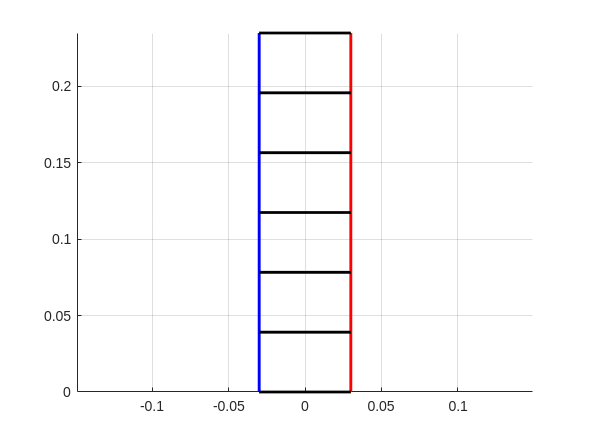

N_seg = 6;
rho = 0.030;
l_0 = 0.235;
arm_30mm = ArmSeriesFactory.constant_2d_muscle_arm(6, rho, l_0);
arm_30mm.segments(1).g_0_o = Pose2.hat([0; 0; pi/2]);
arm_30mm.set_mechanics(GinaMuscleMechanics(l_0));
arm_30mm.solve_equilibrium_gina([0; 0], [0; 0; 0]);

Plotter2D.plot_arm_series(arm_30mm, axes(figure()));

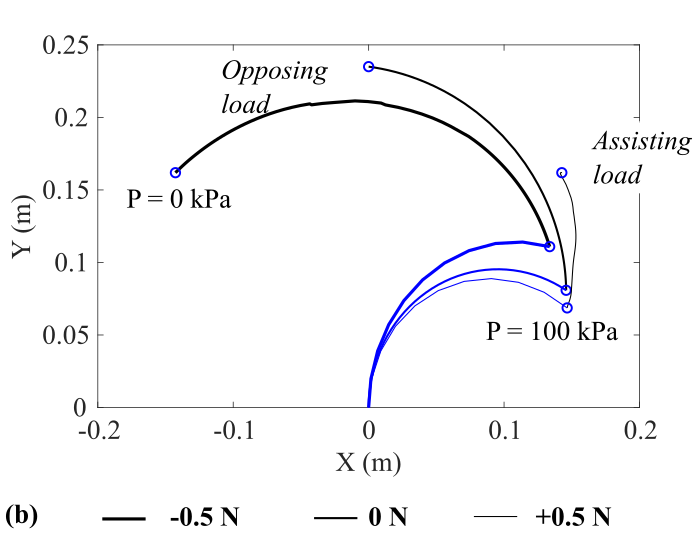

% Sweep right muscle from 0-100kpa with a resisting vs assisting 0.5N loads
N_test_points = 10;
pressures = linspace(0, 100, N_test_points);

ax = axes(figure());
frame = "Tip";

load = [0; -0.5; 0]; % Assisting load
cell_g_circ_right = cell(1, N_test_points);
for i = 1 : N_test_points
    p_i = [pressures(i); 0];
    cell_g_circ_right{i} = arm_30mm.solve_equilibrium_gina(p_i, load, "frame", "Tip");
    Plotter2D.plot_base_curve(arm_30mm, ax, "blue");
end

load = [0; 0.5; 0]; % Resisting load
cell_g_circ_right = cell(N_test_points);
for i = 1 : N_test_points
    p_i = [pressures(i); 0];
    cell_g_circ_right{i} = arm_30mm.solve_equilibrium_gina(p_i, load, "frame", "Tip");
    Plotter2D.plot_base_curve(arm_30mm, ax, "red");
end

### Validate with 30mm wide arm

Validating with a 30mm arm currently runs into convergence issues :(

For this first half, we will test without warm starting. So, the initial guess for fsolve will always be the "straight" configuration.

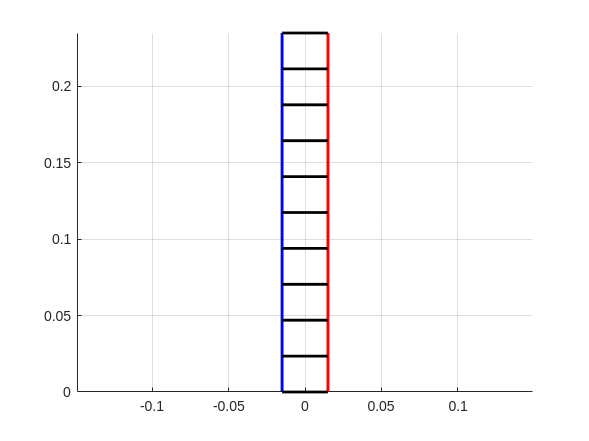

N_seg = 10;
rho = 0.015;
l_0 = 0.235;
arm_30mm = ArmSeriesFactory.constant_2d_muscle_arm(N_seg, rho, l_0);
arm_30mm.segments(1).g_0_o = Pose2.hat([0; 0; pi/2]);
arm_30mm.set_mechanics(GinaMuscleMechanics(l_0));
arm_30mm.solve_equilibrium_gina([0; 0], [0; 0; 0]);

Plotter2D.plot_arm_series(arm_30mm, axes(figure()));

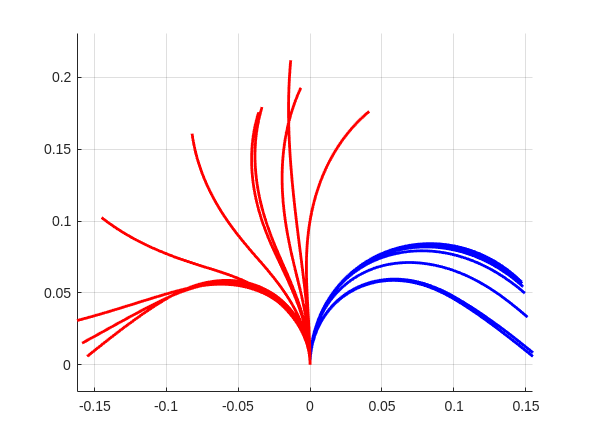

fzero residual is nonzero (> 0.01). Printing: 
  Columns 1 through 8
   -0.0115   -0.0055   -0.0015    0.0006    0.0017    0.0008    0.0013    0.0008
   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001
    0.0609    0.0522    0.0439    0.0359    0.0281    0.0207    0.0129    0.0052
  Columns 9 through 10
    0.0011    0.0003
   -0.0000   -0.0000
   -0.0018   -0.0096
fzero residual is nonzero (> 0.01). Printing: 
  Columns 1 through 8
   -0.0006   -0.0004   -0.0003   -0.0002   -0.0001   -0.0001   -0.0000   -0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.0305    0.0243    0.0186    0.0154    0.0123    0.0096    0.0073    0.0051
  Columns 9 through 10
    0.0000    0.0000
   -0.0000   -0.0000
    0.0025   -0.0000
fzero residual is nonzero (> 0.01). Printing: 
  Columns 1 through 8
   -0.0002   -0.0002   -0.0001   -0.0001   -0.0001   -0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    


% Sweep right muscle from 0-100kpa with a resisting vs assisting 0.5N loads
N_test_points = 10;
pressures = linspace(0, 100, N_test_points);

ax = axes(figure());
frame = "Tip";

load = [0; -0.5; 0]; % Assisting load
cell_g_circ_right = cell(1, N_test_points);
for i = 1 : N_test_points
    p_i = [pressures(i); 0];
    cell_g_circ_right{i} = arm_30mm.solve_equilibrium_gina(p_i, load, "frame", "Tip");
    Plotter2D.plot_base_curve(arm_30mm, ax, "blue");
end

load = [0; 0.5; 0]; % Resisting load
cell_g_circ_right = cell(N_test_points);
for i = 1 : N_test_points
    p_i = [pressures(i); 0];
    cell_g_circ_right{i} = arm_30mm.solve_equilibrium_gina(p_i, load, "frame", "Tip");
    Plotter2D.plot_base_curve(arm_30mm, ax, "red");
end

### Pressure sweep with warm start

For this test, as we resolve with higher actuator pressures, fsolve will be initialized with the solution to the last pressure value.

ax = axes(figure());
frame = "Tip";

load = [0; -0.5; 0]; % Assisting load
cell_g_circ_right = cell(1, N_test_points);
for i = 1 : N_test_points
    p_i = [pressures(i); 0];
    cell_g_circ_right{i} = arm_30mm.solve_equilibrium_gina(p_i, load, "frame", "Tip", "warm_start", true);
    Plotter2D.plot_base_curve(arm_30mm, ax, "blue");
end

load = [0; 0.5; 0]; % Resisting load
cell_g_circ_right = cell(N_test_points);
for i = 1 : N_test_points
    p_i = [pressures(i); 0];
    cell_g_circ_right{i} = arm_30mm.solve_equilibrium_gina(p_i, load, "frame", "Tip", "warm_start", true);
    Plotter2D.plot_base_curve(arm_30mm, ax, "red");
end

### Pressure sweep for world force

For this test, as we resolve with higher actuator pressures, fsolve will be initialized with the solution to the last pressure value.

ax = axes(figure());
frame = "World";

load = [0; -0.5; 0]; % Assisting load
cell_g_circ_right = cell(1, N_test_points);
for i = 1 : N_test_points
    p_i = [pressures(i); 0];
    cell_g_circ_right{i} = arm_30mm.solve_equilibrium_gina(p_i, load, "frame", frame, "warm_start", true, "fast", true);
    Plotter2D.plot_base_curve(arm_30mm, ax, "blue");
end

fzero residual is nonzero (> 0.01). Printing: 
  Columns 1 through 8
    0.0004    0.0000   -0.0000   -0.0000    0.0001    0.0002    0.0002    0.0003
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
   -0.0397   -0.0261   -0.0191   -0.0016    0.0075    0.0110    0.0144    0.0189
  Columns 9 through 10
    0.0004    0.0005
    0.0000   -0.0000
    0.0250    0.0324
fzero residual is nonzero (> 0.01). Printing: 
  Columns 1 through 8
    0.0006    0.0001   -0.0001   -0.0001    0.0000    0.0001    0.0001    0.0002
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
   -0.0482   -0.0244   -0.0195   -0.0074    0.0017    0.0056    0.0086    0.0135
  Columns 9 through 10
    0.0003    0.0004
    0.0000    0.0000
    0.0205    0.0289
fzero residual is nonzero (> 0.01). Printing: 
  Columns 1 through 8
    0.0005    0.0003    0.0001   -0.0002   -0.0003   -0.0002   -0.0001   -0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    

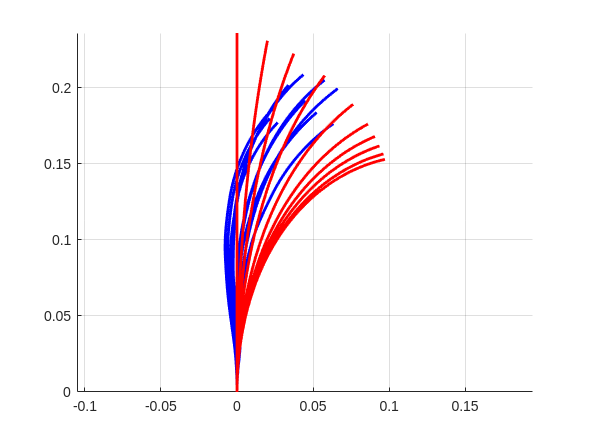


load = [0; 0.5; 0]; % Resisting load
cell_g_circ_right = cell(N_test_points);
for i = 1 : N_test_points
    p_i = [pressures(i); 0];
    cell_g_circ_right{i} = arm_30mm.solve_equilibrium_gina(p_i, load, "frame", frame, "warm_start", true, "fast", true);
    Plotter2D.plot_base_curve(arm_30mm, ax, "red");
end

arm_30mm.solve_equilibrium_gina([pressures(5); 0], load, "frame", "Tip")

loads = [0, 0.25, 0.5, 0.75, 1, 1.13];

cell_g_circ_right = cell(1, length(loads));
ax = axes(figure());
for i = 1 : length(loads)
    current_load = loads(i)
    tic

    N_l_ramp = 5; % Number of loads to ramp up to target load
    load_ramp_up_i = linspace(0, current_load, N_l_ramp);
    for i_lramp = 1 : N_l_ramp
        load_i = load_ramp_up_i(i_lramp);
        arm_30mm.solve_equilibrium_gina([0; 0], [0; load_i; 0], "frame", "Tip");
    end

    N_p_ramp = 10;
    p_ramp_up_i = linspace(0, 100, N_p_ramp);
    for i_pramp = 1 : N_p_ramp
        p_i = p_ramp_up_i(i_pramp);
        g_circ_right_i = arm_30mm.solve_equilibrium_gina([p_i; 0], [0; current_load; 0], "frame", "Tip", "warm_start", true);
    end
    cell_g_circ_right{i} = g_circ_right_i;
    Plotter2D.plot_base_curve(arm_30mm, ax);

    toc
end

current_load = 0

Elapsed time is 6.505854 seconds.


current_load = 0.2500

Elapsed time is 817.246438 seconds.


current_load = 0.5000

Elapsed time is 1365.482733 seconds.


current_load = 0.7500

fzero residual is nonzero (> 0.01). Printing: 
  Columns 1 through 8
   -0.0013   -0.0011   -0.0009   -0.0007   -0.0006   -0.0004   -0.0003   -0.0002
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.0851    0.0765    0.0679    0.0593    0.0506    0.0422    0.0333    0.0249
  Columns 9 through 10
   -0.0001    0.0000
   -0.0000   -0.0000
    0.0164    0.0084
fzero residual is nonzero (> 0.01). Printing: 
  Columns 1 through 8
   -0.0015   -0.0014   -0.0012   -0.0011   -0.0009   -0.0007   -0.0004   -0.0003
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1064    0.0976    0.0882    0.0772    0.0658    0.0542    0.0436    0.0329
  Columns 9 through 10
   -0.0001   -0.0000
   -0.0000   -0.0000
    0.0221    0.0110


fzero residual is nonzero (> 0.01). Printing: 
  Columns 1 through 8
   -0.0015   -0.0014   -0.0012   -0.0011   -0.0009   -0.0007   -0.0004   -0.0003
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1064    0.0976    0.0882    0.0772    0.0658    0.0542    0.0436    0.0329
  Columns 9 through 10
   -0.0001   -0.0000
   -0.0000   -0.0000
    0.0221    0.0110
fzero residual is nonzero (> 0.01). Printing: 
  Columns 1 through 8
   -0.0014   -0.0013   -0.0011   -0.0010   -0.0008   -0.0006   -0.0004   -0.0002
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1026    0.0935    0.0834    0.0740    0.0601    0.0475    0.0351    0.0225
  Columns 9 through 10
   -0.0000    0.0001
   -0.0000   -0.0000
    0.0118   -0.0006
fzero residual is nonzero (> 0.01). Printing: 
  Columns 1 through 8
   -0.0002   -0.0001   -0.0002   -0.0001   -0.0000    0.0000    0.0000    0.0001
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -

Elapsed time is 2687.308206 seconds.


current_load = 1

fzero residual is nonzero (> 0.01). Printing: 
  Columns 1 through 8
   -0.0015   -0.0014   -0.0012   -0.0011   -0.0009   -0.0007   -0.0004   -0.0003
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1064    0.0976    0.0882    0.0772    0.0658    0.0542    0.0436    0.0329
  Columns 9 through 10
   -0.0001   -0.0000
   -0.0000   -0.0000
    0.0221    0.0110
fzero residual is nonzero (> 0.01). Printing: 
  Columns 1 through 8
   -0.0024   -0.0021   -0.0017   -0.0014   -0.0011   -0.0008   -0.0006   -0.0003
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2092    0.1883    0.1675    0.1466    0.1258    0.1050    0.0841    0.0631
  Columns 9 through 10
   -0.0001    0.0001
   -0.0000   -0.0000
    0.0420    0.0209


fzero residual is nonzero (> 0.01). Printing: 
  Columns 1 through 8
   -0.0024   -0.0021   -0.0017   -0.0014   -0.0011   -0.0008   -0.0006   -0.0003
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2092    0.1883    0.1675    0.1466    0.1258    0.1050    0.0841    0.0631
  Columns 9 through 10
   -0.0001    0.0001
   -0.0000   -0.0000
    0.0420    0.0209
fzero residual is nonzero (> 0.01). Printing: 
  Columns 1 through 8
   -0.0047   -0.0109   -0.0118   -0.0122   -0.0132   -0.0221   -0.0113    0.0002
    0.0000    0.0001    0.0002    0.0003    0.0003    0.0003    0.0004    0.0003
    0.1251    0.1210    0.1139    0.1036    0.0855    0.0702    0.0470    0.0415
  Columns 9 through 10
    0.0005    0.0002
    0.0001    0.0000
    0.0248    0.0094
fzero residual is nonzero (> 0.01). Printing: 
  Columns 1 through 8
   -0.0005   -0.0004   -0.0003   -0.0003   -0.0003   -0.0002   -0.0001    0.0000
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -

Elapsed time is 2721.372688 seconds.


current_load = 1.1300

fzero residual is nonzero (> 0.01). Printing: 
  Columns 1 through 8
   -0.0013   -0.0011   -0.0009   -0.0008   -0.0006   -0.0004   -0.0003   -0.0002
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0855    0.0767    0.0686    0.0601    0.0514    0.0432    0.0339    0.0255
  Columns 9 through 10
   -0.0001   -0.0000
    0.0000    0.0000
    0.0167    0.0086
fzero residual is nonzero (> 0.01). Printing: 
  Columns 1 through 8
   -0.0020   -0.0017   -0.0014   -0.0011   -0.0009   -0.0007   -0.0005   -0.0003
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1749    0.1574    0.1402    0.1228    0.1055    0.0880    0.0704    0.0533
  Columns 9 through 10
   -0.0001    0.0001
   -0.0000   -0.0000
    0.0355    0.0180
fzero residual is nonzero (> 0.01). Printing: 
  Columns 1 through 8
   -0.0030   -0.0026   -0.0022   -0.0017   -0.0013   -0.0010   -0.0006   -0.0003
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -

fzero residual is nonzero (> 0.01). Printing: 
  Columns 1 through 8
   -0.0030   -0.0026   -0.0022   -0.0017   -0.0013   -0.0010   -0.0006   -0.0003
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2256    0.2031    0.1804    0.1580    0.1357    0.1130    0.0901    0.0677
  Columns 9 through 10
   -0.0001    0.0002
   -0.0000   -0.0000
    0.0451    0.0225
fzero residual is nonzero (> 0.01). Printing: 
  Columns 1 through 8
   -0.0007   -0.0006   -0.0006   -0.0006   -0.0005   -0.0004   -0.0003   -0.0003
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.0457    0.0452    0.0438    0.0417    0.0392    0.0355    0.0300    0.0238
  Columns 9 through 10
   -0.0001    0.0000
   -0.0000   -0.0000
    0.0127    0.0064
fzero residual is nonzero (> 0.01). Printing: 
  Columns 1 through 8
   -0.0002   -0.0001   -0.0002   -0.0002   -0.0003   -0.0002   -0.0000    0.0000
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -

Elapsed time is 1613.050906 seconds.


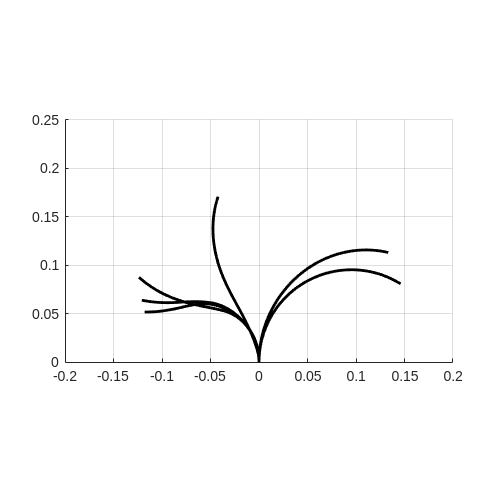

xlim([-0.2, 0.2])
ylim([0, 0.25])
set(gcf, "Position", [0, 0, 500, 500])

ax = axes(figure());
for i = 1 : length(loads)
    arm_30mm.solve_equilibrium_gina([100; 0], [0; loads(i); 0], "frame", "Tip");
    Plotter2D.plot_base_curve(arm_30mm, ax);
end